# Desarrollo Laboratorio 1 - Robótica 2021-II

### Edgar Alejandro Ruíz Velasco

### Jesus Daniel Caballero Colina

### Jhohan David Contreras Aragón

**Para este equipo de trabajo se asignó el robot industrial *****Epson C4***

**Punto 1.**** Determine el modelo geométrico inverso del robot asignado haciendo uso de la metodología explicada en clase. Haga una descripción detallada del proceso haciendo uso de imágenes y dibujos que ayuden visualizar de dónde provienen las ecuaciones encontradas.**

**Punto 2.**** En las soluciones de la inversa incluya consideraciones respecto a multiplicidad de soluciones.  **

Para el robot asignado se tiene las siguientes medidas y movimientos:

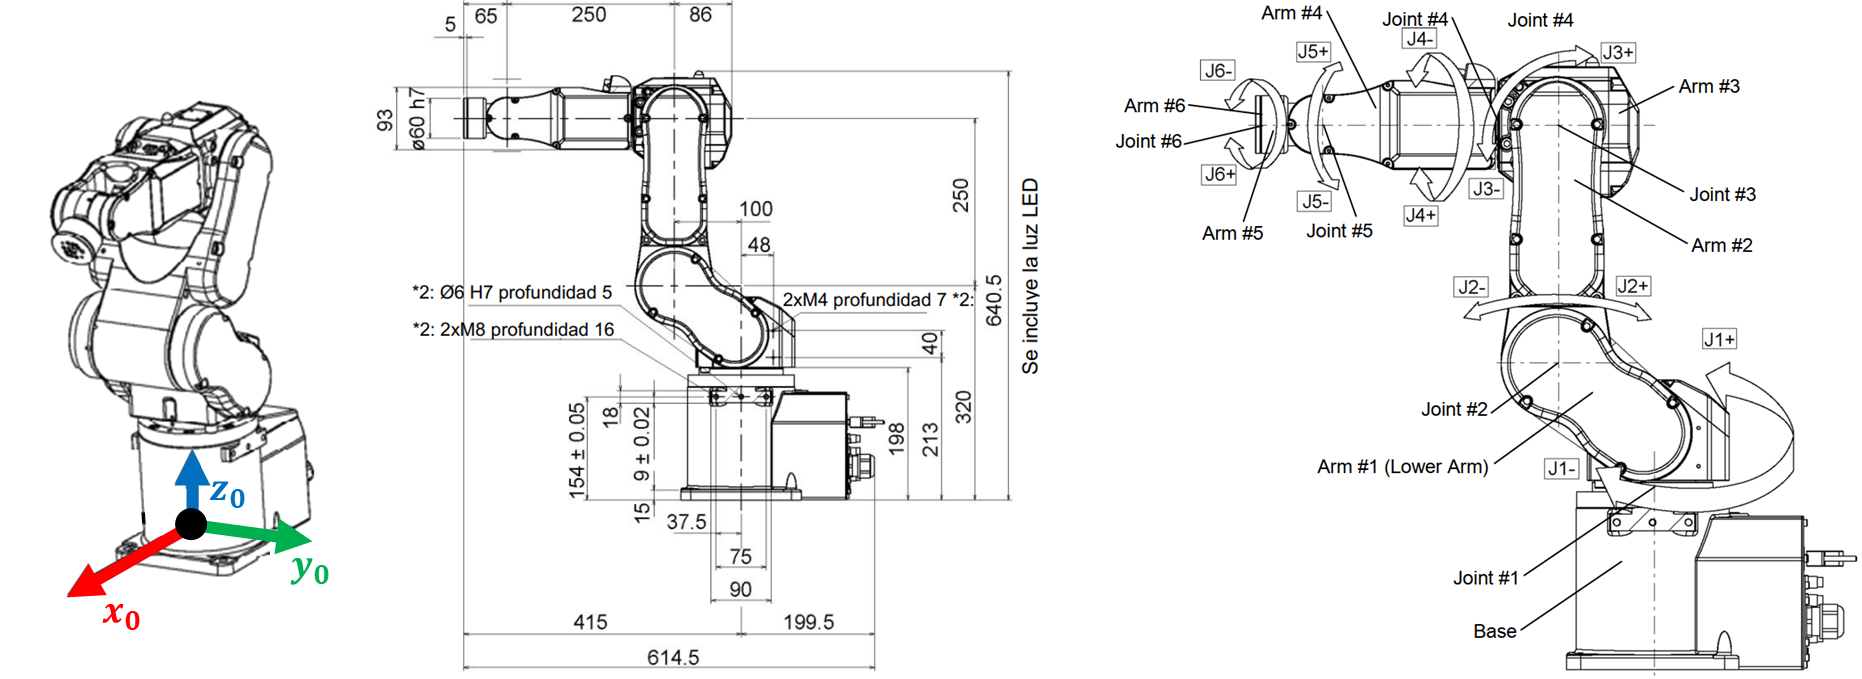

Con las gráficas anterior se realiza la ubicación de MTH y determinación de parámetros DH:

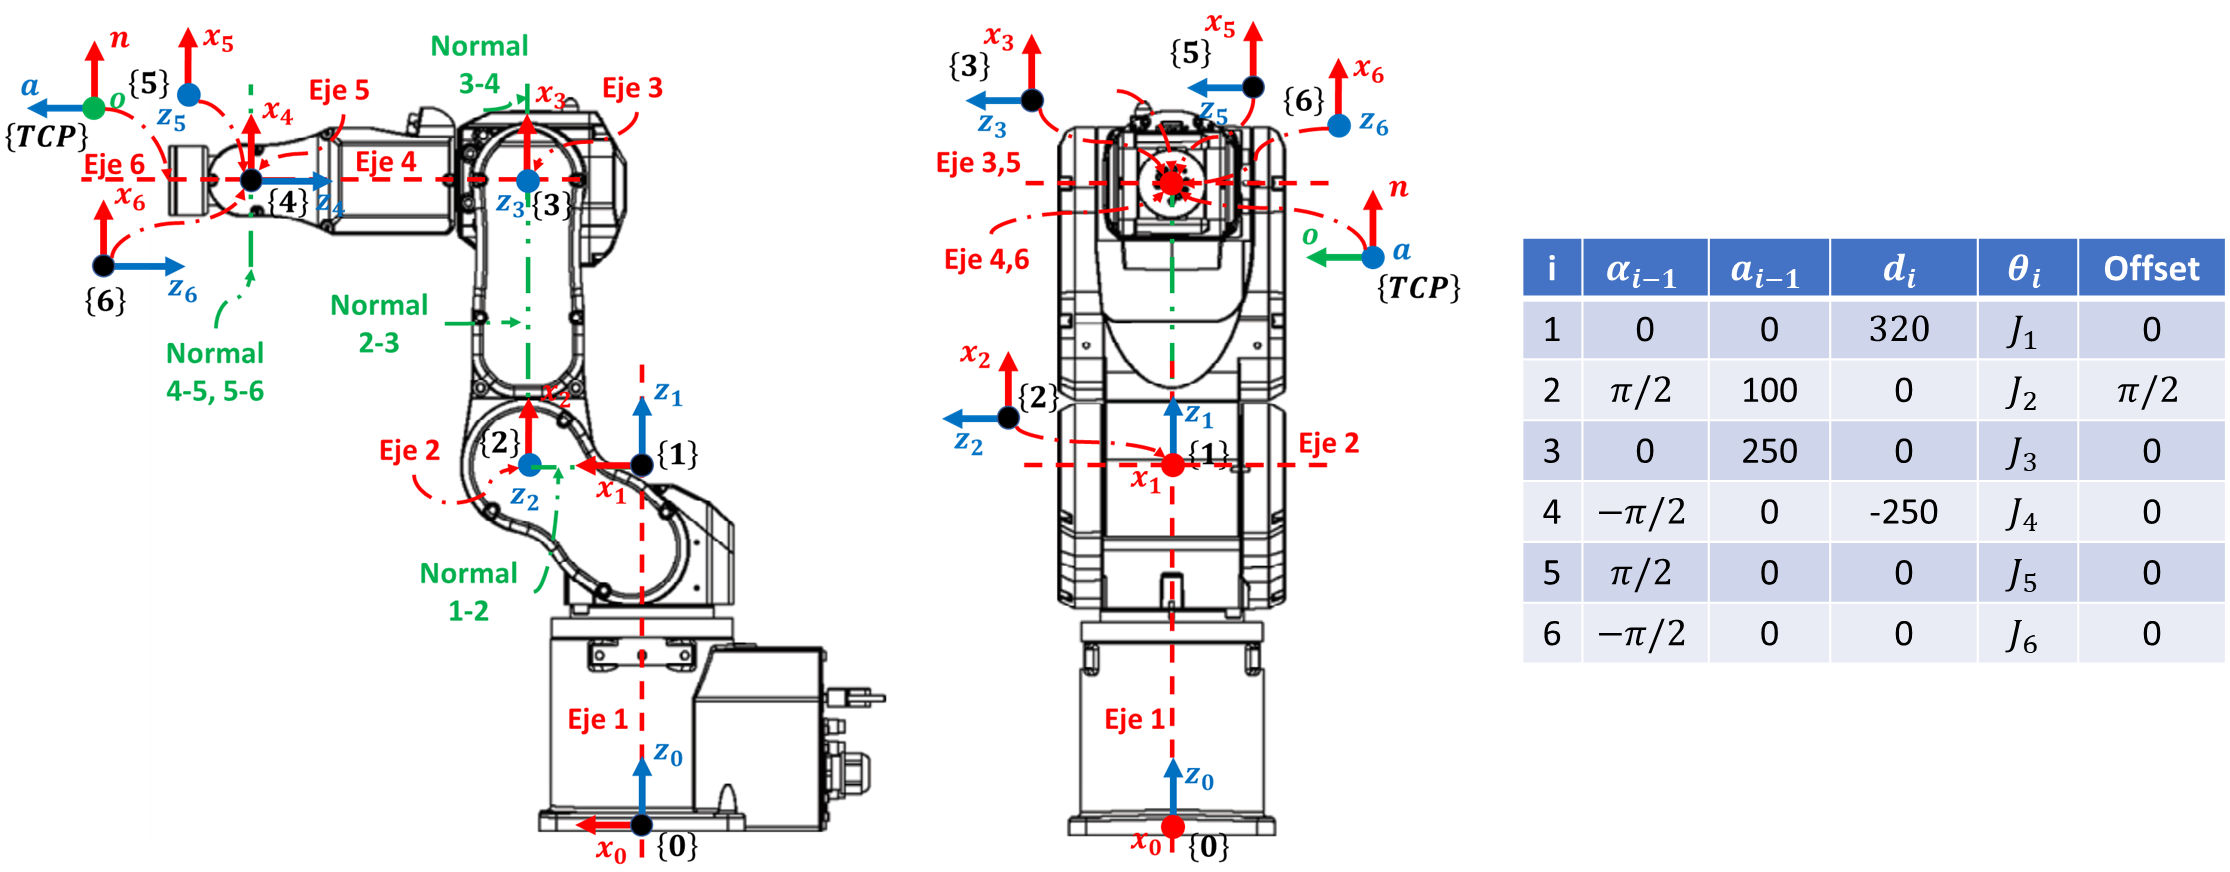

Se observa que las 3 últimas articulaciones (4, 5 y 6) se encuentran en el mismo punto. Aunque la combinación de esas 3 articulaciones no se considere como una junta esférica (y no se pueda aplicar el método Pieper completo) si se puede realizar el método de desacoplamiento cinemático hasta cierto punto. El metodo a usar es:

- Hallar la posición del punto p (posición de los sistemas de referencia 4, 5 y 6) mediante las ecuaciones de MTH

- Por método gráfico, hallar los valores de las 3 primeras articulaciones.

- Por método analítico, hallar el valor de las últimas articulaciones

**Paso 1:**

La ubicación de punto P se halla sabiendo que la pose del TCP está ya determinada. Teniendo que la ubicación de la herramienta es $X_{\textrm{TCP}} ={\left\lbrack \begin{array}{cccccc}
x & y & z & \psi  & \theta  & \phi 
\end{array}\right\rbrack }^T$ (con $\left\lbrack \begin{array}{ccc}
\theta  & \psi  & \phi 
\end{array}\right\rbrack$ ángulos rpy), se halla la matriz de rotación del sistema TCP $R_{\textrm{TCP}}$ :


$$R_{\textrm{TCP}} =\left\lbrack \begin{array}{ccc}
C\phi \ldotp C\theta  & C\phi \ldotp S\theta \ldotp S\psi -S\phi \ldotp C\psi  & C\phi \ldotp S\theta \ldotp C\psi +S\phi \ldotp S\psi \\
S\phi \ldotp C\theta  & S\phi \ldotp S\theta \ldotp S\psi -C\phi \ldotp C\psi  & S\phi \ldotp S\theta \ldotp C\psi -C\phi \ldotp S\psi \\
-S\theta  & C\theta \ldotp S\psi  & C\theta \ldotp C\psi 
\end{array}\right\rbrack$$


 Además se sabe que la posición de p cumple la ecuación:


$$X_P =X_{\textrm{TCP}} -R_{\textrm{TCP}} \left\lbrack \begin{array}{c}
0\\
0\\
65
\end{array}\right\rbrack$$



$$X_P =\left\lbrack \begin{array}{c}
x_{0,4} \\
y_{0,4} \\
z_{0,4} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
x-65\ldotp \left(C\phi \ldotp S\theta \ldotp C\psi +S\phi \ldotp S\psi \right)\\
y-65\ldotp \left(S\phi \ldotp S\theta \ldotp C\psi -C\phi \ldotp S\psi \right)\\
z-65\ldotp \left(C\theta \ldotp C\psi \right)
\end{array}\right\rbrack$$


**Paso 2:**

Los esquemas simplificados que ilustran la ubicación de cada articulación con relación a sus valores son:

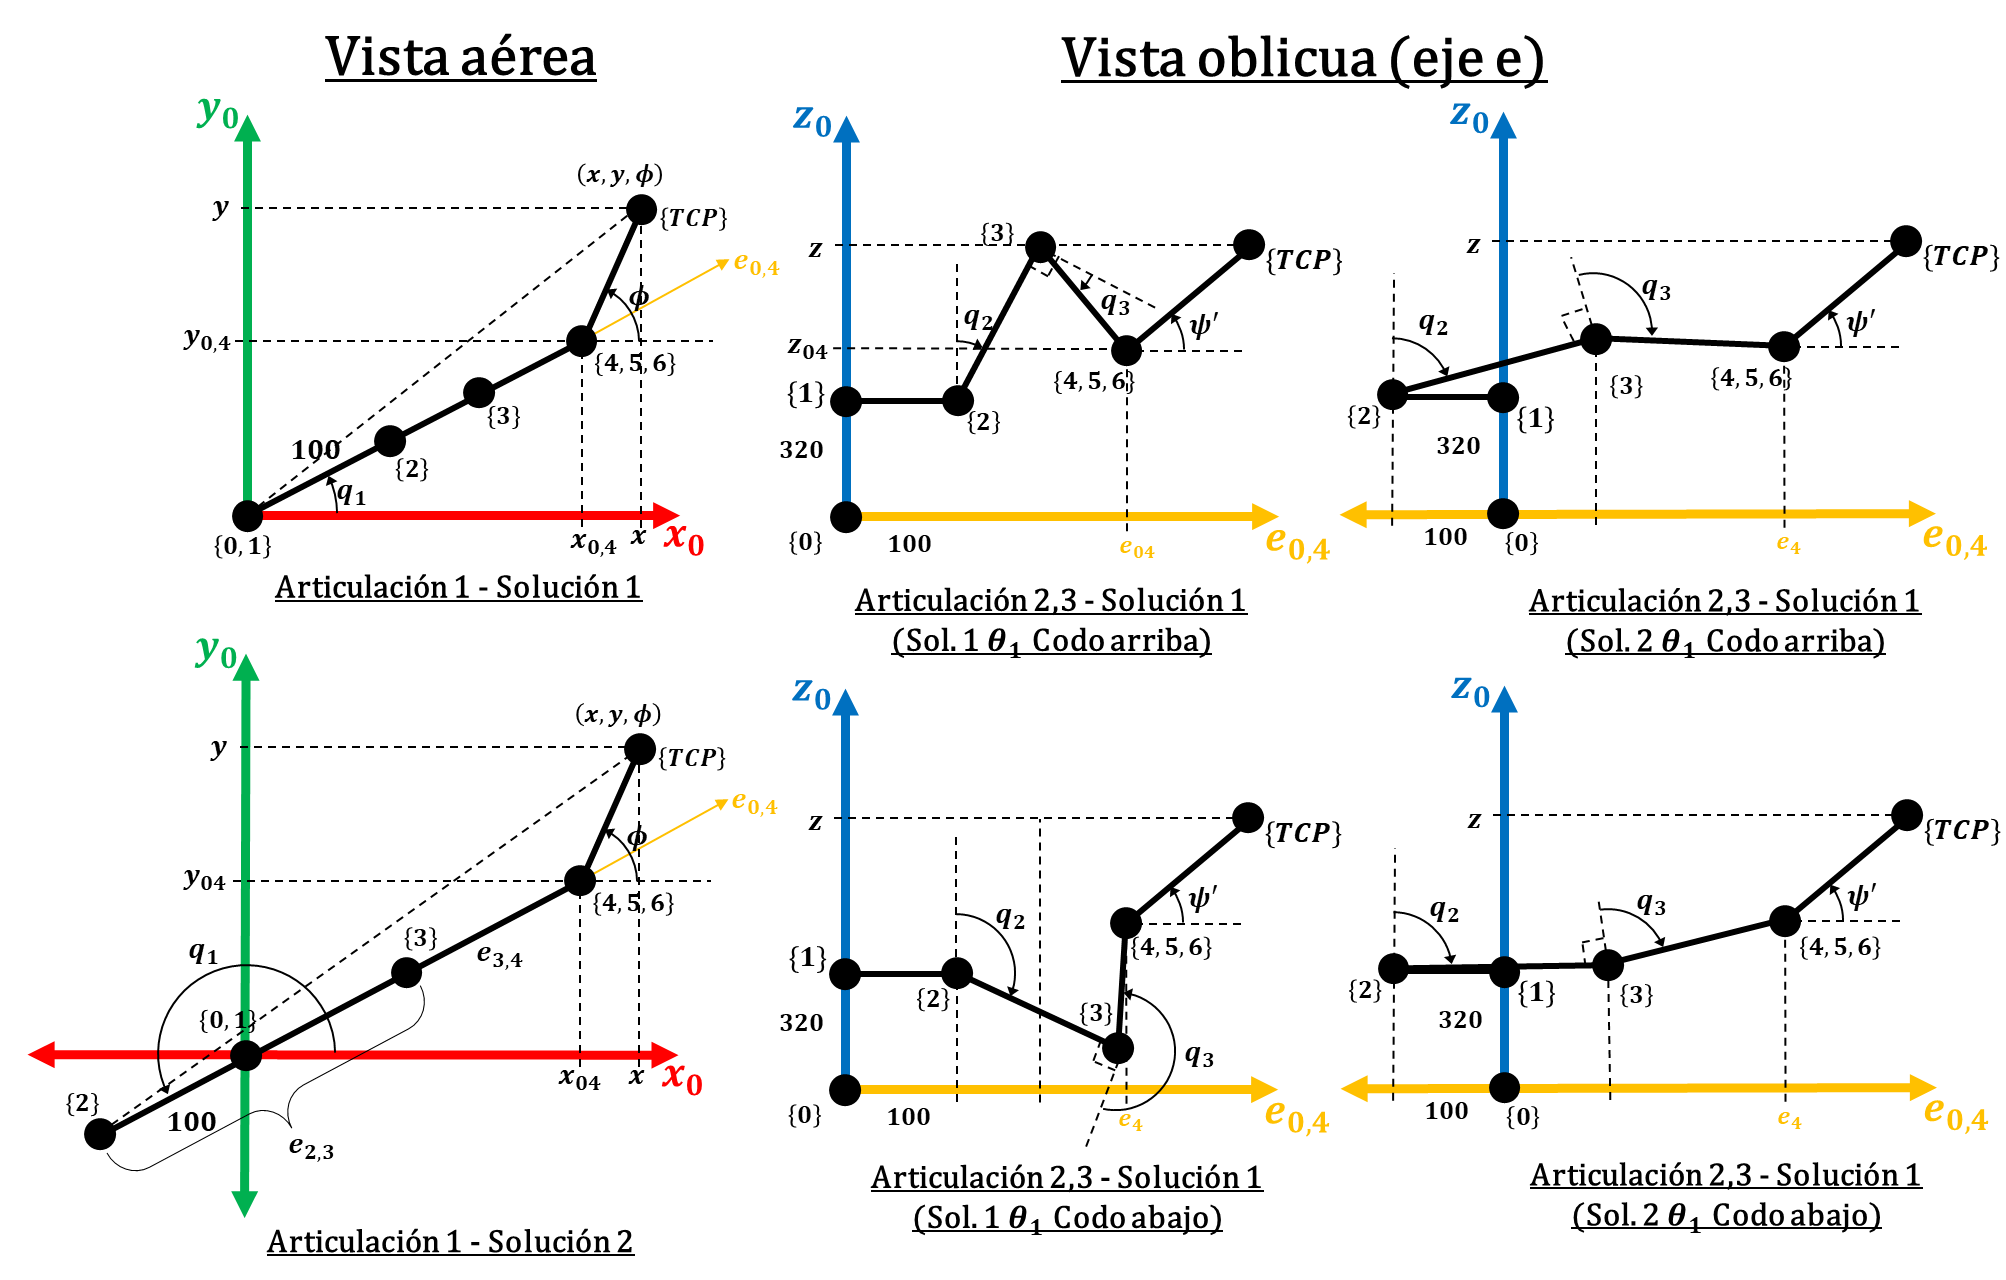

Con la vista aérea se tiene que:

$q_{1;i} =\textrm{atan2}\left(y_{0,4} ,x_{0,4} \right)$ y $q_{1;\textrm{ii}} =\textrm{atan2}\left(y_{0,4} ,x_{0,4} \right)+\pi$

Con la vista oblicua se tiene siguiente esquema:

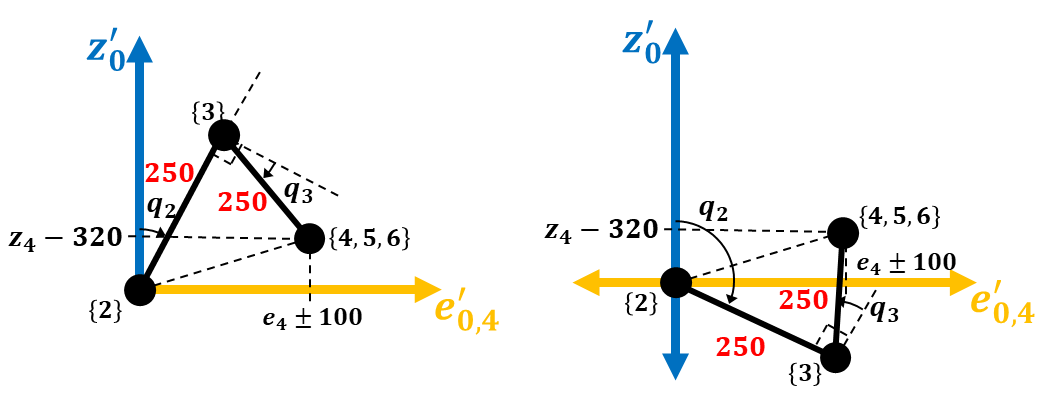

Donde:


$$e_4 =\sqrt{x_4^2 +y_4^2 }$$


Por teorema de cosenos (y teniendo en cuenta las dos soluciones de $\theta_1$):


$${\left(e_4 \pm_1 100\right)}^2 +{\left(z_4 -320\right)}^2 =2\ldotp {250}^2 -2\ldotp {250}^2 \ldotp \cos \left(180-\left(90+q_3 \right)\right)=2\ldotp {250}^2 \left(1+\cos \left(90+q_3 \right)\right)$$



$${\left(e_4 \pm_1 100\right)}^2 +{\left(z_4 -320\right)}^2 =2\ldotp {250}^2 \left(1-\sin \left(q_3 \right)\right)$$



$$\sin \left(q_3 \right)=1-\frac{{\left(e_4 -100\right)}^2 +{\left(z_4 -320\right)}^2 }{2\ldotp {250}^2 }=D_1$$



$$\sin \left(q_3 \right)=1-\frac{{\left(e_4 +100\right)}^2 +{\left(z_4 -320\right)}^2 }{2\ldotp {250}^2 }=D_2$$


Es decir que

$\cos \left(q_3 \right)=\sqrt{1-\sin^2 \left(q_3 \right)}=\pm_2 \sqrt{1-D_1^2 }$ o $\pm_2 \sqrt{1-D_2^2 }$

$q_{3;i,\textrm{ii}} =\textrm{atan2}\left(D_1 ,\pm_2 \sqrt{1-D_1^2 }\right)$o $q_{3;\textrm{iii},\textrm{iv}} =\textrm{atan2}\left(D_1 ,\pm_2 \sqrt{1-D_2^2 }\right)$

Ya teniendo $q_3$ se puede determinar $q_2$ por suma de ángulos:

$q_{2;i,\textrm{ii}} =90-\textrm{atan2}\left(z_4 -320,e_4 -100\right)-\left(45+\frac{q_{3;i,\textrm{ii}} }{2}\right)$ o $q_{2;\textrm{iii},\textrm{iv}} =90-\textrm{atan2}\left(z_4 -320,e_4 +100\right)+\left(45+\frac{q_{3;\textrm{iii},\textrm{iv}} }{2}\right)$

$q_{2;i,\textrm{ii}} =45-\textrm{atan2}\left(z_4 -320,e_4 -100\right)-\frac{q_{3;i,\textrm{ii}} }{2}$ o $q_{2;\textrm{iii},\textrm{iv}} =135-\textrm{atan2}\left(z_4 -320,e_4 +100\right)+\frac{q_{3;\textrm{iii},\textrm{iv}} }{2}$

Es decir que las soluciones quedarían:


$$\left\lbrack \begin{array}{c}
\;\textrm{Sol}\ldotp \\
q_1 \\
q_2 \\
q_3 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
\textrm{Sol}\ldotp 1 & \textrm{Sol}\ldotp 2 & \textrm{Sol}\ldotp 3 & \textrm{Sol}\ldotp 4\\
q_{1,i}  & q_{1,i}  & q_{1,\textrm{ii}}  & q_{1,\textrm{ii}} \\
q_{2,i}  & q_{2,\textrm{ii}}  & q_{2,\textrm{iii}}  & q_{2,\textrm{iv}} \\
q_{3,i}  & q_{3,\textrm{ii}}  & q_{3,\textrm{iii}}  & q_{3,\textrm{iv}} 
\end{array}\right\rbrack$$


**Paso 3:**

Como ya se obtuvo los valores de las 3 primeras articulaciones (de una determinada solución $k$) entonces es conocido el valor de ${}^0_{\;}R^{\;}_3$:


$${}^0_{\;}R^{\;}_3={}^0_{\;}R^{\;}_1\left(q_{1,k} \right)\ldotp {}^1_{\;}R^{\;}_2\left(q_{2,k} \right)\ldotp {}^2_{\;}R^{\;}_3\left(q_{3,k} \right)=\left\lbrack \begin{array}{ccc}
C_1  & -S_1  & 0\\
S_1  & C_1  & 0\\
0 & 0 & 1
\end{array}\right\rbrack \ldotp \left\lbrack \begin{array}{ccc}
C\left(q_2 +\frac{\pi }{2}\right) & -S\left(q_2 +\frac{\pi }{2}\right) & 0\\
0 & 0 & -1\\
S\left(q_2 +\frac{\pi }{2}\right) & C\left(q_2 +\frac{\pi }{2}\right) & 0
\end{array}\right\rbrack \ldotp \left\lbrack \begin{array}{ccc}
C_3  & -S_3  & 0\\
S_3  & C_3  & 0\\
0 & 0 & 1
\end{array}\right\rbrack$$



$${}^0_{\;}R^{\;}_3=\left\lbrack \begin{array}{ccc}
C_1  & -S_1  & 0\\
S_1  & C_1  & 0\\
0 & 0 & 1
\end{array}\right\rbrack \ldotp \left\lbrack \begin{array}{ccc}
-S_2  & -C_2  & 0\\
0 & 0 & -1\\
C_2  & -S_2  & 0
\end{array}\right\rbrack \ldotp \left\lbrack \begin{array}{ccc}
C_3  & -S_3  & 0\\
S_3  & C_3  & 0\\
0 & 0 & 1
\end{array}\right\rbrack$$



$${}^0_{\;}R^{\;}_3=\left\lbrack \begin{array}{ccc}
-C_1 C_2 S_3 -C_1 S_2 C_3  & C_1 S_2 S_3 -C_1 C_2 C_3  & S_1 \\
-S_1 C_2 S_3 -S_1 S_2 C_3  & S_1 S_2 S_3 -S_1 C_2 C_3  & -C_1 \\
C_2 C_3 -S_2 S_3  & -C_2 S_3 -S_2 C_3  & 0
\end{array}\right\rbrack$$


Y por la orientación de la disposición de las 3 últimas articulaciones se sabe que la matriz de rotación desde el sistema 3 al sistema TCP (colocandolos en un mismo origen) ${}^3_{\;}R^{\;}_{\textrm{TCP}}$ tendría un valor de:


$${}^3_{\;}R^{\;}_{\textrm{TCP}}=R_{\textrm{eul},\textrm{ZYZ}} \left(-q_4 ,-q_5 ,-q_6 \right)\ldotp R_x \left(\pi \right)=\left\lbrack \begin{array}{ccc}
-S_4 S_6 +C_4 C_5 C_6  & S_4 C_6 +C_4 C_5 S_6  & -C_4 S_5 \\
-C_4 S_6 -S_4 C_5 C_6  & C_4 C_6 -S_4 C_5 S_6  & S_4 S_5 \\
S_5 C_6  & S_5 S_6  & C_5 
\end{array}\right\rbrack \ldotp \left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & -1 & 0\\
0 & 0 & -1
\end{array}\right\rbrack$$



$${}^3_{\;}R^{\;}_{\textrm{TCP}}=\left\lbrack \begin{array}{ccc}
-S_4 S_6 +C_4 C_5 C_6  & -S_4 C_6 -C_4 C_5 S_6  & C_4 S_5 \\
C_4 S_6 +S_4 C_5 C_6  & C_4 C_6 -S_4 C_5 S_6  & S_4 S_5 \\
-S_5 C_6  & S_5 S_6  & C_5 
\end{array}\right\rbrack$$


Es decir que ${}^3_{\;}R^{\;}_{\textrm{TCP}}$ deseado en termino de $X_{\textrm{TCP}}$ y las 3 primeras articulaciones es:


$${}^3_{\;}R^*_{\textrm{TCP}}={}^0_{\;}R^{\;T}_3\ldotp {}^0_{\;}R^{\;}_{\textrm{TCP}}={\left\lbrack \begin{array}{ccc}
-C_1 C_2 S_3 -C_1 S_2 C_3  & C_1 S_2 S_3 -C_1 C_2 C_3  & S_1 \\
-S_1 C_2 S_3 -S_1 S_2 C_3  & S_1 S_2 S_3 -S_1 C_2 C_3  & -C_1 \\
C_2 C_3 -S_2 S_3  & -C_2 S_3 -S_2 C_3  & 0
\end{array}\right\rbrack }^T \ldotp \left\lbrack \begin{array}{ccc}
C\phi \ldotp C\theta  & C\phi \ldotp S\theta \ldotp S\psi -S\phi \ldotp C\psi  & C\phi \ldotp S\theta \ldotp C\psi +S\phi \ldotp S\psi \\
S\phi \ldotp C\theta  & S\phi \ldotp S\theta \ldotp S\psi -C\phi \ldotp C\psi  & S\phi \ldotp S\theta \ldotp C\psi -C\phi \ldotp S\psi \\
-S\theta  & C\theta \ldotp S\psi  & C\theta \ldotp C\psi 
\end{array}\right\rbrack$$



$${}^3_{\;}R^*_{\textrm{TCP}}=\left\lbrack \begin{array}{ccc}
a_{11}  & a_{12}  & a_{13} \\
a_{21}  & a_{22}  & a_{23} \\
a_{31}  & a_{32}  & a_{33} 
\end{array}\right\rbrack$$


E igualando ${}^3_{\;}R^*_{\textrm{TCP}}$ y ${}^3_{\;}R^{\;}_{\textrm{TCP}}$, se puede obtener las siguientes igualdades:


$$q_4 =\textrm{atan2}\left(a_{23} ,a_{13} \right)$$



$$q_5 =\textrm{atan2}\left(a_{31}^2 +a_{32}^2 ,a_{33} \right)$$



$$q_6 =\textrm{atan2}\left(a_{32} ,-a_{31} \right)$$


Estas ecuaciones se implementaron en el archivo EpsonC4_IC.m

**Punto 3.**** Haga uso de las funciones del RVC para hallar la cinemática inversa de su robot asignado y compruebe los resultados del punto anterior. Ya que existen varias funciones en el *****Toolbox *****explique:**

**¿Cuál es la diferencia entre estas funciones?**

**¿Cuál debe usar para su robot y por qué? (Revise la documentación del *****Toolbox*****)**

**Punto 4.**** Haga uso del RST para hallar la cinemática inversa de su robot asignado y compruebe los resultados anteriores.**

**Punto 5.**** Compare los métodos.**

**Punto 6.**** Compruebe mediante su modelo geométrico inverso la configuración del robot para las posturas de la herramienta halladas en el anterior laboratorio, tales como puntos de calibración.**

El punto de calibración se encuentra en:

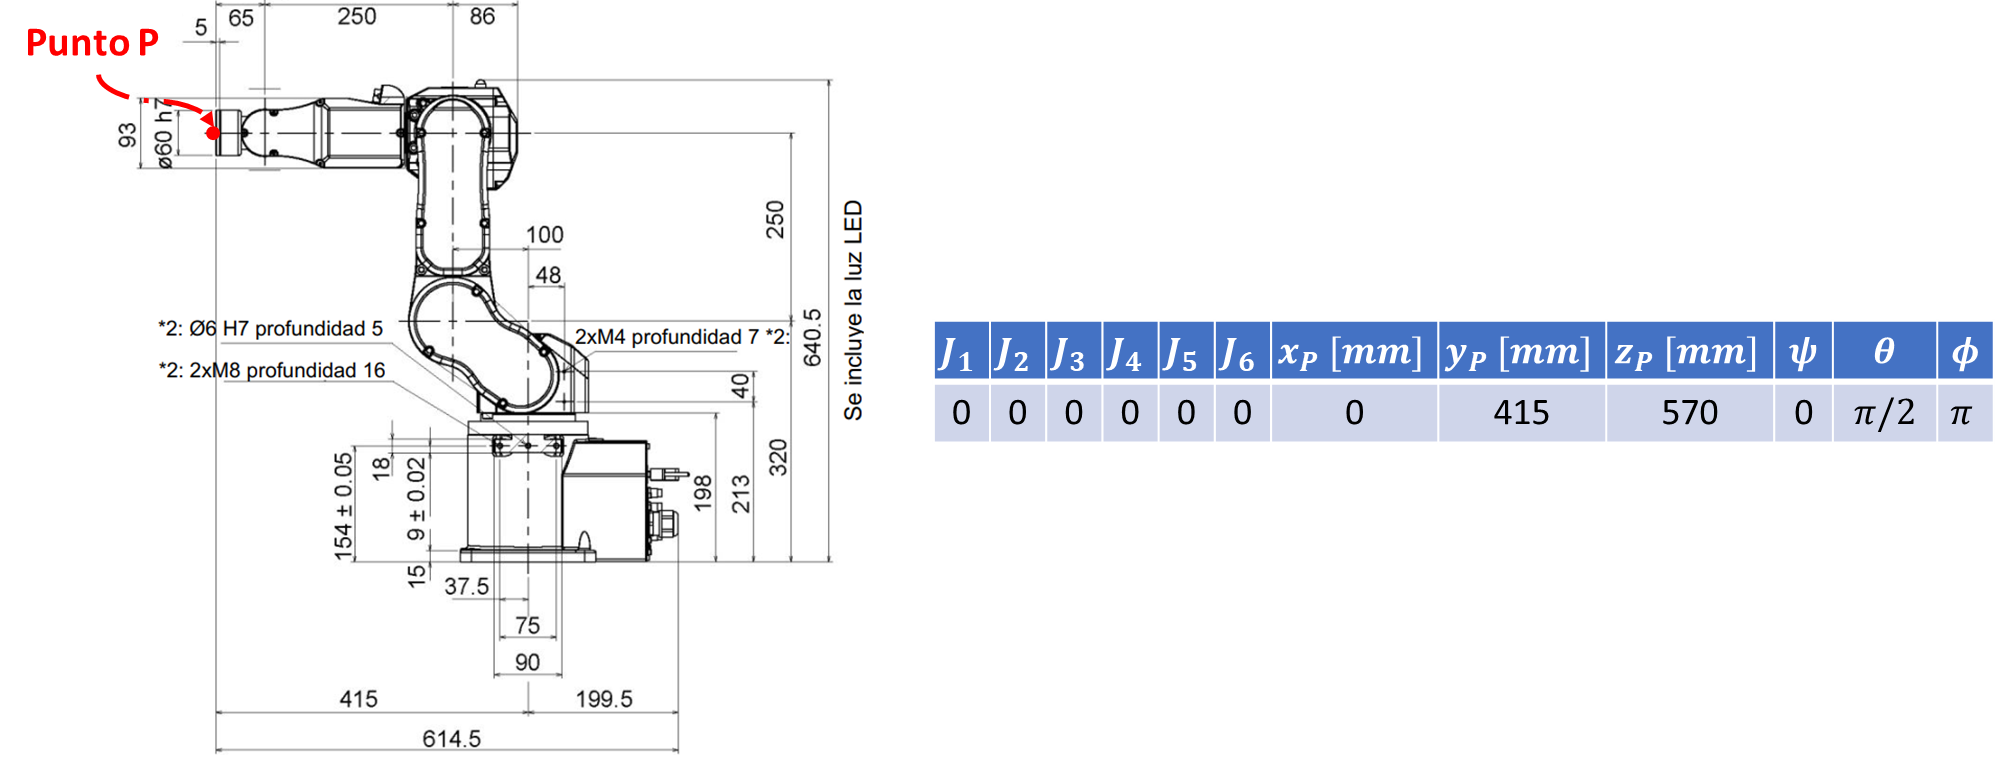

Configs = EpsonC4_IC([415 0 570 0 pi/2 pi])


**Punto 7.**** Proponga 4 posturas (*****x, y, z, roll, pitch, yaw*****)'** **que estén dentro del espacio de trabajo y determine la configuración del manipulador y complete la tabla 1:**

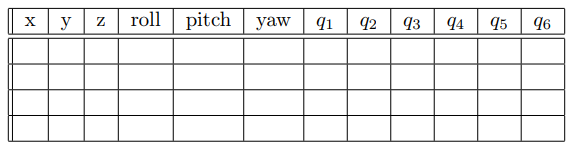

**Punto 8.**** Haciendo uso de la GUI verifique que con la configuración calculada se obtiene la postura indicada de la herramienta. Haga capturas de pantalla resaltando con cotas los valores *****x y z*****, e incluya en el informe los resultados**

**Punto 9.**** Actualice la GUI para que tenga la opción de ingresar la posición de la herramienta, obtener la configuración del robot mediante cinemática inversa y observar el robot en la posición. Compruebe su funcionamiento.**

Configs =          0         0         0         0         0   -0.0000
         0  -90.0000  180.0000         0  -90.0000    0.0000
         0         0         0         0         0         0
         0         0         0         0         0         0
